# Trajectory Generation

**TASK: **Approximate the following trajectory using a set of points.

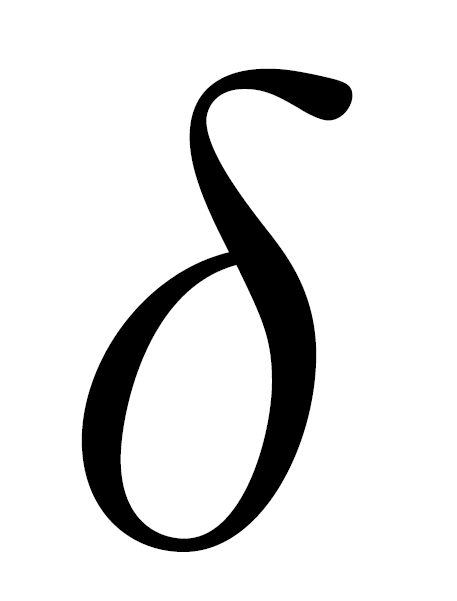

**STRATEGY:** First choose an adequate number of points in the xy plane and then rototranslate them, so that they lie in an inclined plane.

Dimensions are scaled with respect to a unitary box.

clc; clear; close all;

## Shape in the xy plane

#### Sampling points

P1 = [0.90; 0.60; 0]; % Home position
P = [[0.90; 0.07; 0] [0.72; 0.03; 0] [0.55; 0.03; 0] [0.44; 0.08; 0] [0.43; 0.18; 0] ...
     [0.56; 0.33; 0] [0.75; 0.52; 0] [0.75; 0.73; 0] [0.58; 0.92; 0] [0.38; 0.98; 0] ...
     [0.19; 0.94; 0] [0.06; 0.79; 0] [0.16; 0.58; 0] [0.34; 0.45; 0] [0.61; 0.38; 0]]; % Points along the trajectory

#### Curvilinear abscissa

dist = zeros(1,size(P,2));
for i = 2:size(P,2)
    dist(i) = dist(i-1) + norm(P(:,i)-P(:,1));
end

#### Spline interpolation

nPoints_spline = 50;
piecewise_poly = spline(dist(1,:),P(1:2,:));
spline_points = ppval(piecewise_poly,linspace(0,dist(end),nPoints_spline));
spline_points = [spline_points; zeros(1,nPoints_spline)];

#### Plot the sampled trajectory and the interpolated one

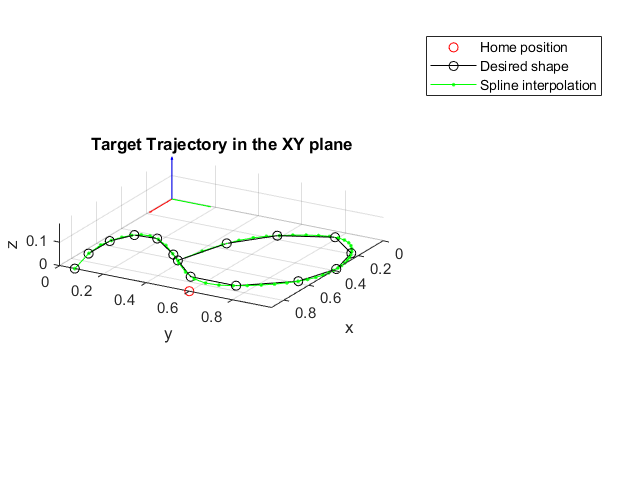

figure
p1 = plot3(P1(1),P1(2),P1(3),'or');
hold on
p2 = plot3(P(1,:),P(2,:),P(3,:),'k-o');
p3 = plot3(spline_points(1,:),spline_points(2,:),spline_points(3,:),'g.-');
grid on

frame_scaling_factor = 5;
plot_frame(eye(3),zeros(3,1),frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title("Target Trajectory in the XY plane")
legend([p1 p2 p3], "Home position", "Desired shape", "Spline interpolation")

## Shape in the XYZ space

#### Specify target plane (rototranslation of the shape)

x_tilt = deg2rad(20);
y_tilt = deg2rad(30);
z_tilt = deg2rad(40);

x_offset = 0.1;
y_offset = 0.3;
z_offset = -0.4;

Rx = [1     0            0
      0 cos(x_tilt) -sin(x_tilt)
      0 sin(x_tilt)  cos(x_tilt)];
  
Ry = [ cos(y_tilt) 0 sin(y_tilt)
           0       1     0
      -sin(y_tilt) 0 cos(y_tilt)];
  
Rz = [cos(z_tilt) -sin(z_tilt) 0
      sin(z_tilt)  cos(z_tilt) 0
          0            0       1];
  
R = Rx*Ry*Rz;

T = [x_offset; y_offset; z_offset];

M_target = [  R   T
            0 0 0 1];
        
P1_homo = [P1; 1];        
P_homo = [P; ones(1,size(P,2))];    
P1_target = M_target*P1_homo;
P_target = M_target*P_homo;

spline_points_homo = [spline_points; ones(1,size(spline_points,2))]; 
spline_points_target = M_target*spline_points_homo;

#### Plot the final, rototranslated, shape of the trajectory (and the interpolated one)

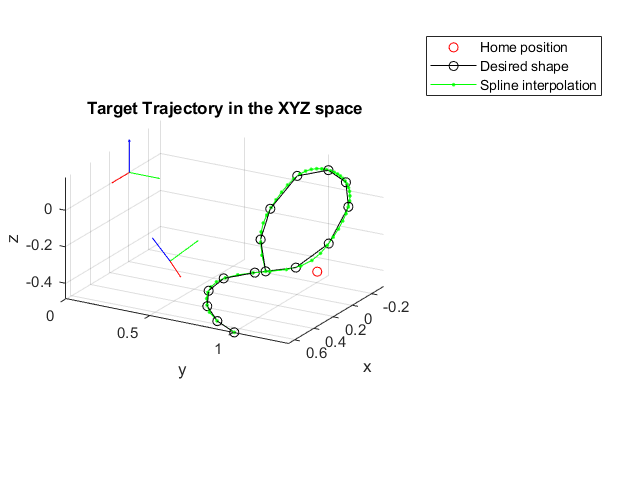

figure
p1 = plot3(P1_target(1),P1_target(2),P1_target(3),'or');
hold on
p2 = plot3(P_target(1,:),P_target(2,:),P_target(3,:),'k-o');
p3 = plot3(spline_points_target(1,:),spline_points_target(2,:),spline_points_target(3,:),'g.-');
grid on

plot_frame(eye(3),zeros(3,1),frame_scaling_factor)
plot_frame(R,T,frame_scaling_factor)

axis equal
xlabel('x'); ylabel('y'); zlabel('z')
view(120,20)
title("Target Trajectory in the XYZ space")
legend([p1 p2 p3], "Home position", "Desired shape", "Spline interpolation")

## Motion task definition

#### Kinematic limits

A = 5;   % Maximum acceleration of the gripper [m/s^2]
D = A;   % Maximum deceleration (absolute value) of the gripper [m/s^2]
V = 10;   % Maximum velocity of the gripper [m/s]

load_data_kinematics;

## From home to the first point of the letter

Minimum actuation time and cycloidal acceleration profile.

The minimum actuation time is clearly achieved along a straight line.

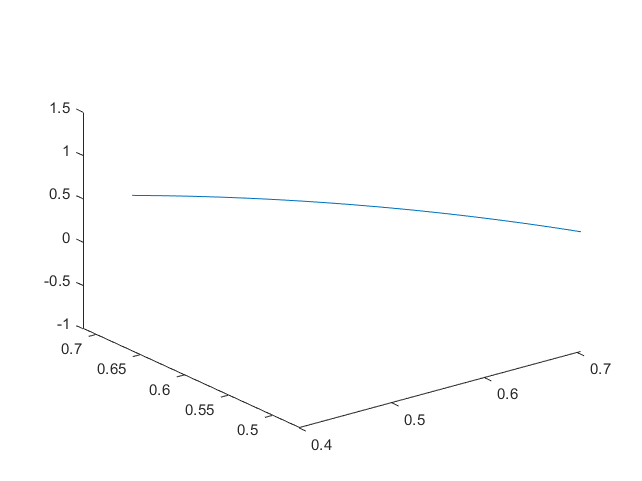

S_home = P1;
S_initial_shape = spline_points_target(1:3,1);

Q0_home = inv_kin(num2cell(S_home),L,angle,1);
Q_home = cell2mat(inv_kin_numerical(num2cell(S_home),L,angle,Q0_home));

Q0_initial_shape = inv_kin(num2cell(S_initial_shape),L,angle,1);
Q_initial_shape = cell2mat(inv_kin_numerical(num2cell(S_initial_shape),L,angle,Q0_initial_shape));

dQ = Q_initial_shape-Q_home;
abs_dQ = norm(dQ);

% Formula for the minimum actuation time in the case of cycloidal law of motion
Ttot = max([2*abs_dQ/V sqrt(2*pi*abs_dQ/A) sqrt(2*pi*abs_dQ/D)]);

syms l1a l1b l1c l2 l3 tilt_angle q1_sym(t) q2_sym(t) q3_sym(t) q1p_sym(t) q2p_sym(t) q3p_sym(t)
Qsymb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t)];
Qp_symb = [l1a; l1b; l1c; l2; l3; tilt_angle; q1_sym(t); q2_sym(t); q3_sym(t); q1p_sym(t); q2p_sym(t); q3p_sym(t)];

% Compute symbolic jacobian and its derivative w.r.t. time
[J_symb,~] = jac_symb;
[Jp_symb,~] = jacP_symb;

% Number of points in which to compute the law of motion
nPoints = 100;

Q = zeros(3,nPoints);   Qp = zeros(3,nPoints);  Qpp = zeros(3,nPoints);
S = zeros(3,nPoints);   Sp = zeros(3,nPoints);  Spp = zeros(3,nPoints);
pos = zeros(1,nPoints);

tt = linspace(0,Ttot,nPoints);
for i = 1:nPoints
    % GRIPPER COORDINATES
    [q1,q1p,q1pp] = cycloidal_given_limits(tt(i),A,Q_home(1),dQ(1));
    [q2,q2p,q2pp] = cycloidal_given_limits(tt(i),A,Q_home(2),dQ(2));
    [q3,q3p,q3pp] = cycloidal_given_limits(tt(i),A,Q_home(3),dQ(3));
    
    Q(:,i) = real([q1; q2; q3]);
    Qp(:,i) = real([q1p; q2p; q3p]);
    Qpp(:,i) = real([q1pp; q2pp; q3pp]);
    
    % COORDINATES THROUGH DIRECT KINEMATICS
    [Scell,~] = dir_kin(num2cell(Q(:,i)),L,angle);
    S(:,i) = cell2mat(Scell);

    % CONVERT FROM SYMBOLIC TO NUMERICAL VALUES
    J = double(subs(J_symb,Qsymb,[L'; angle; Q(:,i)]));
    Jp = double(subs(Jp_symb,Qp_symb,[L'; angle; Q(:,i); Qp(:,i)]));
    
    % VELOCITY ARRAY
    Sp(:,i) = J*Qp(:,i);    
    
    % ACCELERATION ARRAY
    Spp(:,i) = J*Qpp(:,i)+Jp*Qp(:,i);
    
    % POSITION OF THE GRIPPER ALONG THE TRAJECTORY
    % (velocity and acceleration are computed afterwards using diff()/dT)
    pos(i) = norm(S(1:3,i) - S(1:3,1));
        
    %%%%% END KINEMATICS %%%%%
end

plot3(S(1,:),S(2,:),S(3,:))

## Along the shape of the letter

Points connected using the spline algorithm

## From the last point of the letter back to home

Minimum actuation time and cycloidal acceleration profile